clc; clear; close all

syms M m l g u y y_dot theta theta_dot t q1 q2

## Output 1

% Define the system state
x = [y; y_dot; theta; theta_dot];

% Define system dynamics
y_ddot=(-m*l*sin(theta)*theta_dot^2 + m*g*sin(theta)*cos(theta) + u)/...
    (M + m*sin(theta)^2);

theta_ddot=(-m*l*sin(theta)*cos(theta)*theta_dot^2 + (M+m)*g*sin(theta) +...
    u*cos(theta))/...
    (l*(M+m*sin(theta)^2));

xdot = [y_dot; y_ddot; theta_dot;theta_ddot];


% Define the set of parameters specific to our ODE
parameters.M = 1.0731;
parameters.m = 0.2300;
parameters.l= 0.3302;
parameters.g = 9.8;

% Start linearizing

% equilibrium point
x_bar = [0; 0; 0; 0];
u_bar = 0;

% find jacobian for any point x
A_raw = jacobian(xdot,x);
B_raw = jacobian(xdot,u);

% substitute parameters as defined above
A_specific = subs(subs(subs(subs(A_raw,m,parameters.m),M,parameters.M), l, parameters.l), g, parameters.g);
B_specific = subs(subs(subs(subs(B_raw,m,parameters.m),M,parameters.M), l, parameters.l), g, parameters.g);

% find jacobian for equilibrium point
A = subs(subs(A_specific,x,x_bar), u, u_bar)

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & \frac{460}{219} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{13031000}{361569} & 0 \end{array}\right)$$

B = subs(subs(B_specific,x,x_bar), u, u_bar)

$$B = \left(\begin{array}{c} 0\\ \frac{10000}{10731}\\ 0\\ \frac{50000000}{17716881} \end{array}\right)$$

## Output 2

% coverting A and B to double precision
A_double = double(A);
B_double = double(B);

% Defining the two sets of poles used for this part
poles_1 = [-1, -2, -3, -4];
poles_2 = [-1, -2, -3, -20];

% Generating gain vectors for the sets of pole locations shown above
negK_1 = place(A_double, B_double,poles_1);
negK_2 = place(A_double, B_double,poles_2);
K_1 = -negK_1               % to convert to the convention used in class

K_1 =     0.8678    1.8078  -25.4587   -4.1403


K_2 = -negK_2               % to convert to the convention used in class

K_2 =     4.3388    8.1715  -60.6213  -11.9110



% Sanity check of closed loop poles_1 -> all poles_1 are at desired locations: [-1, -2, -3, -4]
A_cl_1 = A+B*K_1;           % close-loop system
double(eig(A_cl_1))

ans =   -4.0000 - 0.0000i
  -3.0000 - 0.0000i
  -2.0000 + 0.0000i
  -1.0000 + 0.0000i



% Sanity check of closed loop poles_2 -> all poles_2 are at desired locations: [-1, -2, -3, -20]
A_cl_2 = A+B*K_2;           % close-loop system
double(eig(A_cl_2))

ans =  -20.0000 - 0.0000i
  -3.0000 - 0.0000i
  -2.0000 - 0.0000i
  -1.0000 + 0.0000i


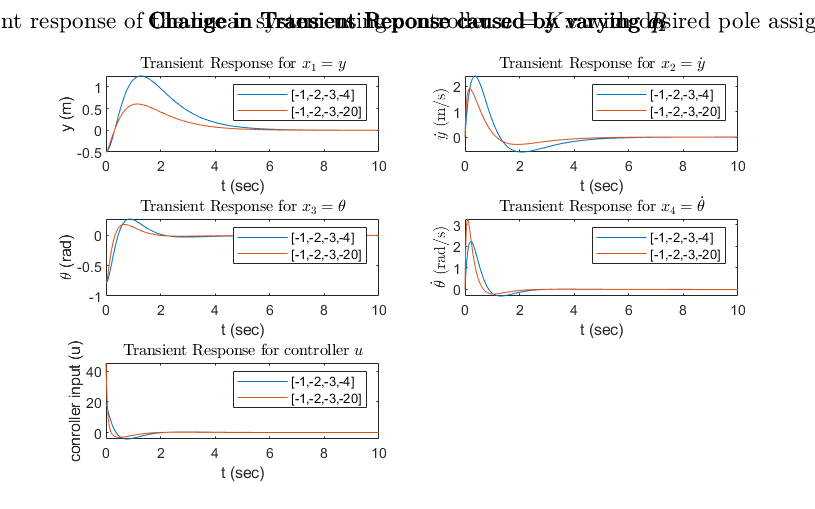


% Create the linearized close-loop system for ploes_1
Xdot_linearized_controlled_1 = A_cl_1 * x;
inverted_pen_1 = matlabFunction(Xdot_linearized_controlled_1,'Vars',{t, x});

% Create the linearized close-loop system for ploes_2
Xdot_linearized_controlled_2 = A_cl_2 * x;
inverted_pen_2 = matlabFunction(Xdot_linearized_controlled_2,'Vars',{t, x});

% ODE solver options
options = odeset('RelTol',1e-7,'AbsTol',1e-7);  
Tspan = linspace(0,10,1e3);

% Solving for both sets of poles for the initial value mentioned below
x0 = [-0.5; 0; -pi/4; 0];
[t_val_1,x_val_1]=ode45(inverted_pen_1,Tspan,x0,options);
[t_val_2,x_val_2]=ode45(inverted_pen_2,Tspan,x0,options);


% Plotting Transient response of the linear system for different pole
% assignments

subplot(3,2,1)              %plotting y
plot(t_val_1, x_val_1(:,1))
hold on                     
plot(t_val_2, x_val_2(:,1))
legend('[-1,-2,-3,-4]', '[-1,-2,-3,-20]')
xlabel("t (sec)")
ylabel("y (m)")
title('Transient Response for $x_1 = y$', 'Interpreter','latex')

subplot(3,2,2)              %plotting y_dot
plot(t_val_1, x_val_1(:,2))
hold on
plot(t_val_2, x_val_2(:,2))
legend('[-1,-2,-3,-4]', '[-1,-2,-3,-20]')
xlabel("t (sec)")
ylabel("$\dot{y}$ (m/s)", 'Interpreter','latex')
title('Transient Response for $x_2 = \dot{y}$', 'Interpreter','latex')

subplot(3,2,3)              %plotting theta
plot(t_val_1, x_val_1(:,3))
hold on
plot(t_val_2, x_val_2(:,3))
legend('[-1,-2,-3,-4]', '[-1,-2,-3,-20]')
xlabel("t (sec)")
ylabel("\theta (rad)")
title('Transient Response for $x_3 = \theta$', 'Interpreter','latex')

subplot(3,2,4)              %plotting theta_dot
plot(t_val_1, x_val_1(:,4))
hold on
plot(t_val_2, x_val_2(:,4))
legend('[-1,-2,-3,-4]', '[-1,-2,-3,-20]')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
title('Transient Response for $x_4 = \dot{\theta}$', 'Interpreter','latex')
subplot(3,2,5)              %plotting control input u
u_1 = -negK_1*x_val_1';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_2 = -negK_2*x_val_2';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_n_by_1_1 = u_1';                      % convert u to Nx1 as requested in lab manual
u_n_by_1_2 = u_2';                      % convert u to Nx1 as requested in lab manual

plot(t_val_1, u_n_by_1_1)   
hold on
plot(t_val_1, u_n_by_1_2)
legend('[-1,-2,-3,-4]', '[-1,-2,-3,-20]')
xlabel("t (sec)")
ylabel("conroller input (u)")
title('Transient Response for controller $u$', 'Interpreter','latex')
set(gcf,'units','points','position',[0,0,800,500])
sgtitle('Transient response of the linear system using controller $u=Kx$ with desired pole assignments', 'Interpreter','latex')


% response:more negative poles -> more drastic response -> less transient
% time; all states are affected; 
Qc = ctrb(A_double,B_double);       % obtain the controllability matrix of the system
rank(Qc)                            % Matrix Rank = 4. So, its fully controllable

ans = 4

P_basis = orth(Qc)

P_basis =    -0.0584    0.0000   -0.9983   -0.0000
   -0.0000    0.0584   -0.0000    0.9983
   -0.9983         0    0.0584         0
   -0.0000    0.9983   -0.0000   -0.0584


% because each basis of P has non-zero coordinate in both the cartposition
% subsystem, and pendulum subsystem, it is IMPOSSIBLE to decouple the 2
% subsystems -> cannot speed up the cart position convergence ALONE.

## Output 3

% Defining Q
Q_base = [q1, 0, 0, 0;
    0, 0, 0, 0;
    0, 0, q2, 0'
    0, 0, 0, 0];

% Creating the state space system for matrix A and B
sys = ss(A_double, B_double, [], []);

%%%%%%%%%%%%%%%%%%%%% Varying q1

q1_val_1 = 0.1;
q1_val_2 = 0.005;
q2_val = 5;
R = [0.5];

%obtain the Q matrix for each configuration of q1
Q_q1_1 = double(subs(subs(Q_base, q2, q2_val), q1, q1_val_1));
Q_q1_2 = double(subs(subs(Q_base, q2, q2_val), q1, q1_val_2));

negK_1 = lqr(sys, Q_q1_1,R);
negK_2 = lqr(sys, Q_q1_2,R);
K_1 = -negK_1               % to convert to the convention used in class

K_1 =     0.4472    1.2429  -29.6951   -4.9864


K_2 = -negK_2               % to convert to the convention used in class

K_2 =     0.1000    0.5509  -27.6408   -4.6051


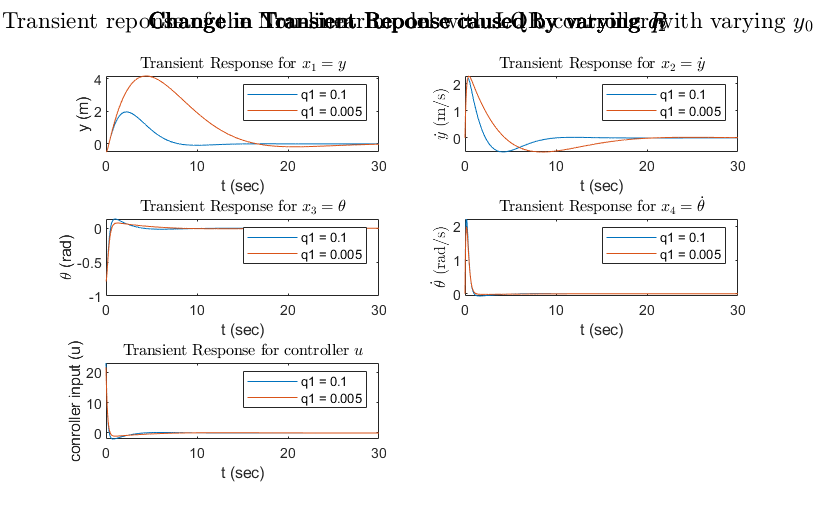


A_cl_1 = A+B*K_1;           % close-loop system 1
A_cl_2 = A+B*K_2;           % close-loop system 2


% Create the linearized close-loop system
Xdot_linearized_controlled_1 = A_cl_1 * x;
inverted_pen_1 = matlabFunction(Xdot_linearized_controlled_1,'Vars',{t, x});

Xdot_linearized_controlled_2 = A_cl_2 * x;
inverted_pen_2 = matlabFunction(Xdot_linearized_controlled_2,'Vars',{t, x});


options = odeset('RelTol',1e-7,'AbsTol',1e-7);  
Tspan = linspace(0,30,3e3);

x0 = [-0.5; 0; -pi/4; 0];
[t_val_1,x_val_1]=ode45(inverted_pen_1,Tspan,x0,options);
[t_val_2,x_val_2]=ode45(inverted_pen_2,Tspan,x0,options);


% Change in Transient Reponse caused by varying q_1
figure
subplot(3,2,1)              %plotting y
plot(t_val_1, x_val_1(:,1))
hold on                     
plot(t_val_2, x_val_2(:,1))
legend('q1 = 0.1', 'q1 = 0.005')
xlabel("t (sec)")
ylabel("y (m)")
title('Transient Response for $x_1 = y$', 'Interpreter','latex')
subplot(3,2,2)              %plotting y_dot
plot(t_val_1, x_val_1(:,2))
hold on
plot(t_val_2, x_val_2(:,2))
legend('q1 = 0.1', 'q1 = 0.005')
xlabel("t (sec)")
ylabel("$\dot{y}$ (m/s)", 'Interpreter','latex')
title('Transient Response for $x_2 = \dot{y}$', 'Interpreter','latex')
subplot(3,2,3)              %plotting theta
plot(t_val_1, x_val_1(:,3))
hold on
plot(t_val_2, x_val_2(:,3))
legend('q1 = 0.1', 'q1 = 0.005')
xlabel("t (sec)")
ylabel("\theta (rad)")
title('Transient Response for $x_3 = \theta$', 'Interpreter','latex')
subplot(3,2,4)              %plotting theta_dot
plot(t_val_1, x_val_1(:,4))
hold on
plot(t_val_2, x_val_2(:,4))
legend('q1 = 0.1', 'q1 = 0.005')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
title('Transient Response for $x_4 = \dot{\theta}$', 'Interpreter','latex')
subplot(3,2,5)              %plotting control input u
u_1 = -negK_1*x_val_1';                 % input u = Kx; convert rows of x_val_1 to become columns of x's
u_2 = -negK_2*x_val_2';                 % input u = Kx; convert rows of x_val_1 to become columns of x's
u_n_by_1_1 = u_1';                       % convert u to Nx1 as requested in lab manual
u_n_by_1_2 = u_2';                       % convert u to Nx1 as requested in lab manual

plot(t_val_1, u_n_by_1_1)   
hold on
plot(t_val_1, u_n_by_1_2)
legend('q1 = 0.1', 'q1 = 0.005')
xlabel("t (sec)")
ylabel("conroller input (u)")
title('Transient Response for controller $u$', 'Interpreter','latex')
set(gcf,'units','points','position',[0,0,800,500])
sgtitle('Change in Transient Reponse caused by varying $q_1$', 'Interpreter','latex')



%%%%%%%%%%%%%%%%%%%%% Varying q2

q1_val = 0.05;
q2_val_1 = 1;
q2_val_2 = 2000;

R = [0.5];

% Obtain the Q matrix for each configuration of q2
Q_q2_1 = double(subs(subs(Q_base, q2, q2_val_1), q1, q1_val));
Q_q2_2 = double(subs(subs(Q_base, q2, q2_val_2), q1, q1_val));

% Getting two gain matrices for two Q matrices
negK_1 = lqr(sys, Q_q2_1,R);
negK_2 = lqr(sys, Q_q2_2,R);
K_1 = -negK_1               % to convert to the convention used in class

K_1 =     0.3162    1.0162  -28.7703   -4.8427


K_2 = -negK_2               % to convert to the convention used in class

K_2 =     0.3162    2.0785  -79.7095   -8.1972


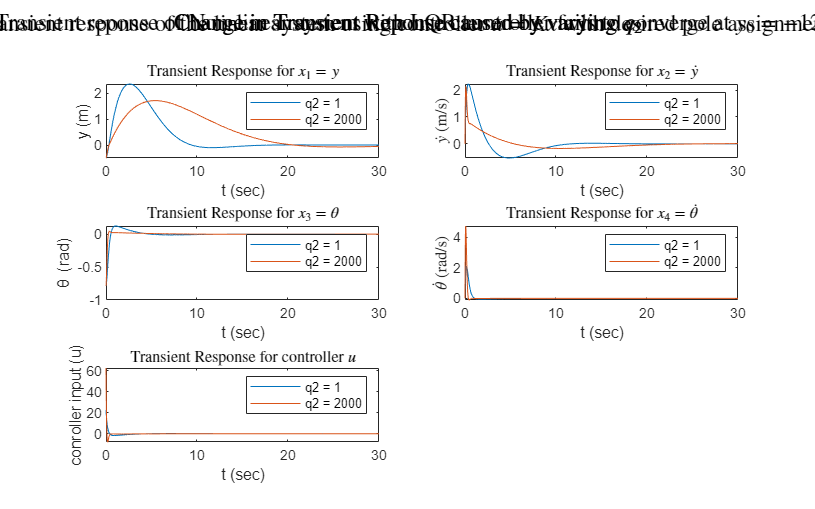


A_cl_1 = A+B*K_1;           % close-loop system 1
A_cl_2 = A+B*K_2;           % close-loop system 2

% create the linearized close-loop system
Xdot_linearized_controlled_1 = A_cl_1 * x;
inverted_pen_1 = matlabFunction(Xdot_linearized_controlled_1,'Vars',{t, x});

Xdot_linearized_controlled_2 = A_cl_2 * x;
inverted_pen_2 = matlabFunction(Xdot_linearized_controlled_2,'Vars',{t, x});


options = odeset('RelTol',1e-7,'AbsTol',1e-7);  

x0 = [-0.5; 0; -pi/4; 0];
[t_val_1,x_val_1]=ode45(inverted_pen_1,Tspan,x0,options);
[t_val_2,x_val_2]=ode45(inverted_pen_2,Tspan,x0,options);


%plotting figures
figure
subplot(3,2,1)              %plotting y
plot(t_val_1, x_val_1(:,1))
hold on                     
plot(t_val_2, x_val_2(:,1))
legend('q2 = 1', 'q2 = 2000')
xlabel("t (sec)")
ylabel("y (m)")
title('Transient Response for $x_1 = y$', 'Interpreter','latex')

subplot(3,2,2)              %plotting y_dot
plot(t_val_1, x_val_1(:,2))
hold on
plot(t_val_2, x_val_2(:,2))
legend('q2 = 1', 'q2 = 2000')
xlabel("t (sec)")
ylabel("$\dot{y}$ (m/s)", 'Interpreter','latex')
title('Transient Response for $x_2 = \dot{y}$', 'Interpreter','latex')

subplot(3,2,3)              %plotting theta
plot(t_val_1, x_val_1(:,3))
hold on
plot(t_val_2, x_val_2(:,3))
legend('q2 = 1', 'q2 = 2000')
xlabel("t (sec)")
ylabel("\theta (rad)")
title('Transient Response for $x_3 = \theta$', 'Interpreter','latex')

subplot(3,2,4)              %plotting theta_dot
plot(t_val_1, x_val_1(:,4))
hold on
plot(t_val_2, x_val_2(:,4))
legend('q2 = 1', 'q2 = 2000')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
title('Transient Response for $x_4 = \dot{\theta}$', 'Interpreter','latex')
subplot(3,2,5)                          %plotting control input u
u_1 = -negK_1*x_val_1';                 % input u = Kx; convert rows of x_val_1 to become columns of x's
u_2 = -negK_2*x_val_2';                 % input u = Kx; convert rows of x_val_1 to become columns of x's
u_n_by_1_1 = u_1';                      % convert u to Nx1 as requested in lab manual
u_n_by_1_2 = u_2';                      % convert u to Nx1 as requested in lab manual

plot(t_val_1, u_n_by_1_1)   
hold on
plot(t_val_1, u_n_by_1_2)
legend('q2 = 1', 'q2 = 2000')
xlabel("t (sec)")
ylabel("conroller input (u)")
title('Transient Response for controller $u$', 'Interpreter','latex')
set(gcf,'units','points','position',[0,0,800,500])
sgtitle('Change in Transient Reponse caused by varying $q_2$', 'Interpreter','latex')


%%%%%%%%%%%%%%%%%%%%% varying R

q1_val = 0.05;
q2_val = 5;

R_1 = [0.005];
R_2 = [10];

%obtain the Q matrix for given q1 and q2
Q = double(subs(subs(Q_base, q2, q2_val), q1, q1_val));

% Getting two gain matrices for two values of R
negK_1 = lqr(sys, Q, R_1);
negK_2 = lqr(sys, Q, R_2);
K_1 = -negK_1               % to convert to the convention used in class

K_1 =     3.1623    5.2894  -56.1219   -7.9941


K_2 = -negK_2               % to convert to the convention used in class

K_2 =     0.0707    0.4532  -27.0041   -4.5224


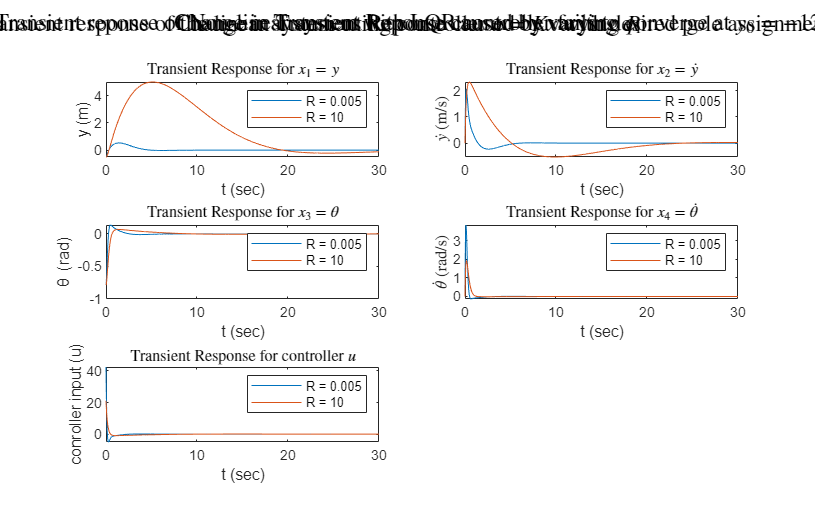


A_cl_1 = A+B*K_1;           % close-loop system 1
A_cl_2 = A+B*K_2;           % close-loop system 2

% create the linearized close-loop system
Xdot_linearized_controlled_1 = A_cl_1 * x;
inverted_pen_1 = matlabFunction(Xdot_linearized_controlled_1,'Vars',{t, x});

Xdot_linearized_controlled_2 = A_cl_2 * x;
inverted_pen_2 = matlabFunction(Xdot_linearized_controlled_2,'Vars',{t, x});


options = odeset('RelTol',1e-7,'AbsTol',1e-7);  

x0 = [-0.5; 0; -pi/4; 0];
[t_val_1,x_val_1]=ode45(inverted_pen_1,Tspan,x0,options);
[t_val_2,x_val_2]=ode45(inverted_pen_2,Tspan,x0,options);


% Plotting Change in Transient Reponse caused by varying R
figure
subplot(3,2,1)              %plotting y
plot(t_val_1, x_val_1(:,1))
hold on                     
plot(t_val_2, x_val_2(:,1))
legend('R = 0.005', 'R = 10')
xlabel("t (sec)")
ylabel("y (m)")
title('Transient Response for $x_1 = y$', 'Interpreter','latex')

subplot(3,2,2)              %plotting y_dot
plot(t_val_1, x_val_1(:,2))
hold on
plot(t_val_2, x_val_2(:,2))
legend('R = 0.005', 'R = 10')
xlabel("t (sec)")
ylabel("$\dot{y}$ (m/s)", 'Interpreter','latex')
title('Transient Response for $x_2 = \dot{y}$', 'Interpreter','latex')

subplot(3,2,3)              %plotting theta
plot(t_val_1, x_val_1(:,3))
hold on
plot(t_val_2, x_val_2(:,3))
legend('R = 0.005', 'R = 10')
xlabel("t (sec)")
ylabel("\theta (rad)")
title('Transient Response for $x_3 = \theta$', 'Interpreter','latex')

subplot(3,2,4)              %plotting theta_dot
plot(t_val_1, x_val_1(:,4))
hold on
plot(t_val_2, x_val_2(:,4))
legend('R = 0.005', 'R = 10')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
title('Transient Response for $x_4 = \dot{\theta}$', 'Interpreter','latex')
subplot(3,2,5)              %plotting control input u
u_1 = -negK_1*x_val_1';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_2 = -negK_2*x_val_2';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_n_by_1_1 = u_1';                       % convert u to Nx1 as requested in lab manual
u_n_by_1_2 = u_2';                       % convert u to Nx1 as requested in lab manual

plot(t_val_1, u_n_by_1_1)   
hold on
plot(t_val_1, u_n_by_1_2)
legend('R = 0.005', 'R = 10')
xlabel("t (sec)")
ylabel("conroller input (u)")
title('Transient Response for controller $u$', 'Interpreter','latex')
set(gcf,'units','points','position',[0,0,800,500])
sgtitle('Change in Transient Reponse caused by varying $R$', 'Interpreter','latex')





% Respone: 
% larger q2 causes the response in theta to be more rapid (larger changes
% in shorter time), while decreasing the settling time in y. larger q1
% causes the response in y to be more rapid (larger changes in shorter 
% time), while decreasing the settling time/performancein theta. 

% (my guess, not too sure) increasing R increases the settling time of both
% outputs (theta, y). An interesting note: the transient time of y is
% significantly more than the transient time of theta because q1 is 100
% times less than q2.



## Output 4


q1_val = 0.05;
q2_val = 5;
R = [0.005];

% Obtain the Q matrix for each configuration of q1
Q = double(subs(subs(Q_base, q2, q2_val), q1, q1_val));

negK = lqr(sys, Q, R);
K = -negK               % to convert to the convention used in class

K =     3.1623    5.2894  -56.1219   -7.9941


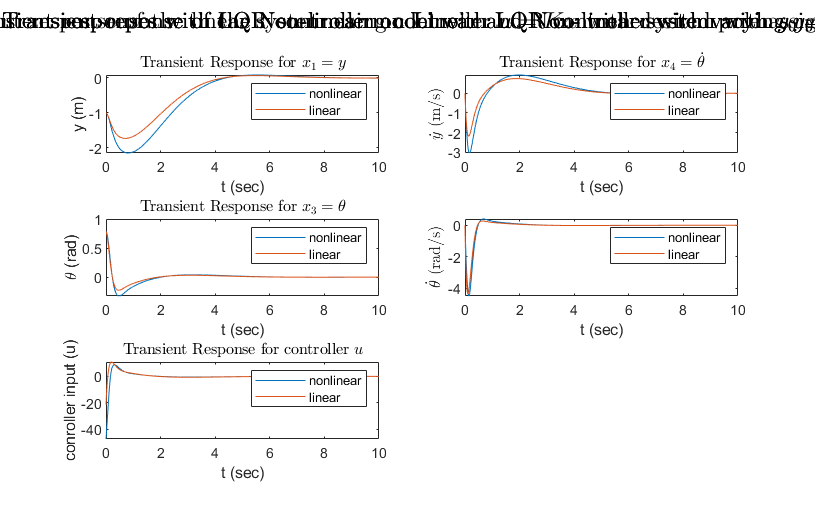


% Nonlinear system x_dot = f(x,u), with parameters substituted
xdot_specific = subs(subs(subs(subs(xdot,m,parameters.m),M,parameters.M), l, parameters.l), g, parameters.g);
xdot_specific_controlled = subs(xdot_specific,u,K*x);
inverted_pen_nonlinear = matlabFunction(xdot_specific_controlled,'Vars',{t, x});

% Linearized system
Xdot_linearized_controlled = (A+B*K) * x;
inverted_pen_linear = matlabFunction(Xdot_linearized_controlled,'Vars',{t, x});


% Simulate both systems
options = odeset('RelTol',1e-7,'AbsTol',1e-7);  
Tspan = linspace(0,10,1e3);

x0 = [-1; 0; pi/4; 0];  % initial conditions
[t_val_nl, x_val_nl]=ode45(inverted_pen_nonlinear,Tspan,x0,options);
[t_val_l, x_val_l]=ode45(inverted_pen_linear,Tspan,x0,options);


% Plotting Transient responses with LQR controller on Linear and Non-linear system
figure
subplot(3,2,1)              %plotting y
plot(t_val_nl, x_val_nl(:,1))
hold on                     
plot(t_val_l, x_val_l(:,1))
legend('nonlinear', 'linear')
xlabel("t (sec)")
ylabel("y (m)")
title('Transient Response for $x_1 = y$', 'Interpreter','latex')

subplot(3,2,2)              %plotting y_dot
plot(t_val_nl, x_val_nl(:,2))
hold on                     
plot(t_val_l, x_val_l(:,2))
legend('nonlinear', 'linear')
xlabel("t (sec)")
ylabel("$\dot{y}$ (m/s)", 'Interpreter','latex')
title('Transient Response for $x_2 = \dot{y}$', 'Interpreter','latex')

subplot(3,2,3)              %plotting theta
plot(t_val_nl, x_val_nl(:,3))
hold on                     
plot(t_val_l, x_val_l(:,3))
legend('nonlinear', 'linear')
xlabel("t (sec)")
ylabel("\theta (rad)")
title('Transient Response for $x_3 = \theta$', 'Interpreter','latex')

subplot(3,2,4)              %plotting theta_dot
plot(t_val_nl, x_val_nl(:,4))
hold on                     
plot(t_val_l, x_val_l(:,4))
legend('nonlinear', 'linear')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
set(gcf,'units','points','position',[0,0,800,500])
title('Transient Response for $x_4 = \dot{\theta}$', 'Interpreter','latex')
subplot(3,2,5)              %plotting control input u
u_1 = -negK_1*x_val_nl';                % input u = Kx; convert rows of x_val_1 to become columns of x's
u_2 = -negK_2*x_val_l';                 % input u = Kx; convert rows of x_val_1 to become columns of x's
u_n_by_1_1 = u_1';                      % convert u to Nx1 as requested in lab manual
u_n_by_1_2 = u_2';                      % convert u to Nx1 as requested in lab manual

plot(t_val_nl, u_n_by_1_1)   
hold on
plot(t_val_l, u_n_by_1_2)
legend('nonlinear', 'linear')
xlabel("t (sec)")
ylabel("conroller input (u)")
title('Transient Response for controller $u$', 'Interpreter','latex')
sgtitle('Transient responses with LQR controller on Linear and Non-linear system with $y_0 = -1$', 'Interpreter','latex')



%%%%%%%%%%%%%%%%%% Plotting divergence plot for non-linear system
y0_val = -12;            % initial y position where states start diverging
q1_val = 0.05;
q2_val = 5;
R = [0.005];

% Obtain the Q matrix for each configuration of q1
Q = double(subs(subs(Q_base, q2, q2_val), q1, q1_val));

negK = lqr(sys, Q, R);
K = -negK               % to convert to the convention used in class

K =     3.1623    5.2894  -56.1219   -7.9941


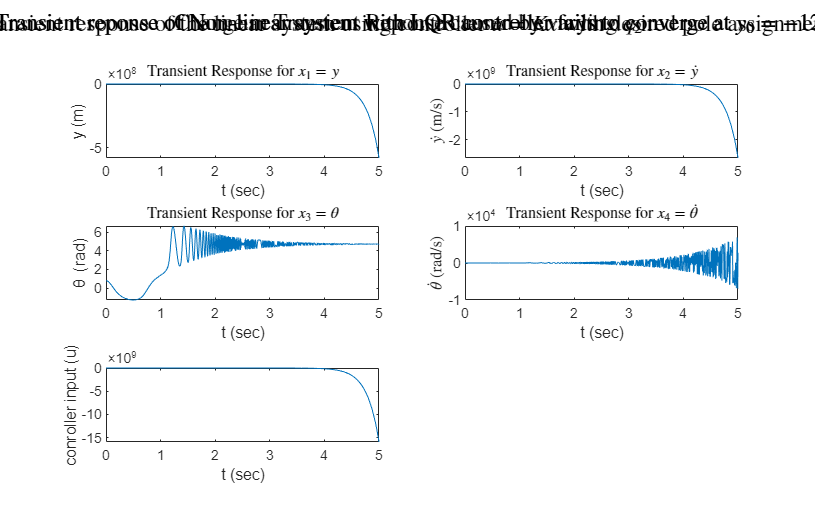


% Nonlinear system x_dot = f(x,u), with parameters substituted
xdot_specific = subs(subs(subs(subs(xdot,m,parameters.m),M,parameters.M), l, parameters.l), g, parameters.g);
xdot_specific_controlled = subs(xdot_specific,u,K*x);
inverted_pen_nonlinear = matlabFunction(xdot_specific_controlled,'Vars',{t, x});


% Simulate the nonlinear system systems
options = odeset('RelTol',1e-7,'AbsTol',1e-7);  
Tspan = linspace(0,5,1e3);

x0 = [y0_val; 0; pi/4; 0];
[t_val_nl, x_val_nl]=ode45(inverted_pen_nonlinear,Tspan,x0,options);


% Plotting Transient reponse of Non-linear system with LQR controller when it fails to converge
figure
subplot(3,2,1)              %plotting y
plot(t_val_nl, x_val_nl(:,1))
xlabel("t (sec)")
ylabel("y (m)")
title('Transient Response for $x_1 = y$', 'Interpreter','latex')

subplot(3,2,2)              %plotting y_dot
plot(t_val_nl, x_val_nl(:,2))
xlabel("t (sec)")
ylabel("$\dot{y}$ (m/s)", 'Interpreter','latex')
title('Transient Response for $x_2 = \dot{y}$', 'Interpreter','latex')

subplot(3,2,3)              %plotting theta
plot(t_val_nl, x_val_nl(:,3))
xlabel("t (sec)")
ylabel("\theta (rad)")
title('Transient Response for $x_3 = \theta$', 'Interpreter','latex')

subplot(3,2,4)              %plotting theta_dot
plot(t_val_nl, x_val_nl(:,4))
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
title('Transient Response for $x_4 = \dot{\theta}$', 'Interpreter','latex')
subplot(3,2,5)              %plotting control input u
u_1 = -negK_1*x_val_nl';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_n_by_1_1 = u_1';                       % convert u to Nx1 as requested in lab manual

plot(t_val_nl, u_n_by_1_1)   
xlabel("t (sec)")
ylabel("conroller input (u)")
set(gcf,'units','points','position',[0,0,800,500])
sgtitle('Transient reponse of Non-linear system with LQR controller fails to converge at  $y_0= -12$', 'Interpreter','latex')

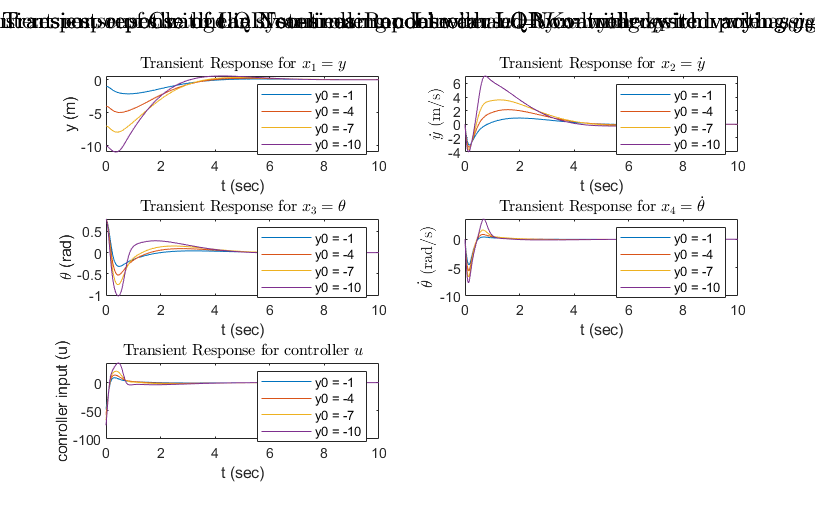


%discussion:
% had to reduce the time span to 0-5 because at t=5, y is already -5e8.
% Beyond this point, the system runs into numerical error and stalls

%%%%%%%%%%%%%%%%%% Plotting for varying y_0 for non-linear system

Tspan = linspace(0,10,1e3);
figure
for y0_val=1:3:11
    x0 = [-y0_val; 0; pi/4; 0];
    [t_val_nl, x_val_nl]=ode45(inverted_pen_nonlinear,Tspan,x0,options);
    
    
    subplot(3,2,1)              %plotting y
    plot(t_val_nl, x_val_nl(:,1),'DisplayName',sprintf("y0 = %d",-y0_val))
    legend
    hold on
    xlabel("t (sec)")
    ylabel("y (m)")
    title('Transient Response for $x_1 = y$', 'Interpreter','latex')

    subplot(3,2,2)              %plotting y_dot
    plot(t_val_nl, x_val_nl(:,2),'DisplayName',sprintf("y0 = %d",-y0_val))
    legend
    hold on
    xlabel("t (sec)")
    ylabel("$\dot{y}$ (m/s)", 'Interpreter','latex')
    title('Transient Response for $x_2 = \dot{y}$', 'Interpreter','latex')

    subplot(3,2,3)              %plotting theta
    plot(t_val_nl, x_val_nl(:,3),'DisplayName',sprintf("y0 = %d",-y0_val))
    legend
    hold on
    xlabel("t (sec)")
    ylabel("\theta (rad)")
    title('Transient Response for $x_3 = \theta$', 'Interpreter','latex')
    
    subplot(3,2,4)              %plotting theta_dot
    plot(t_val_nl, x_val_nl(:,4),'DisplayName',sprintf("y0 = %d",-y0_val))
    legend
    hold on
    xlabel("t (sec)")
    ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
    title('Transient Response for $x_4 = \dot{\theta}$', 'Interpreter','latex')
    subplot(3,2,5)              %plotting control input u
    u_1 = -negK_1*x_val_nl';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
    u_n_by_1_1 = u_1';                       % convert u to Nx1 as requested in lab manual
    u_n_by_1_2 = u_2';                       % convert u to Nx1 as requested in lab manual
    
    plot(t_val_nl, u_n_by_1_1,'DisplayName',sprintf("y0 = %d",-y0_val))
    legend 
    hold on
    xlabel("t (sec)")
    ylabel("conroller input (u)")
    title('Transient Response for controller $u$', 'Interpreter','latex')
    set(gcf,'units','points','position',[0,0,800,500])
    sgtitle('Transient reponse of the Non-linear model with LQR controller with varying $y_0$', 'Interpreter','latex')
end